# Chapter 3. LED Night Light

B. Rasnow 31May25

## Objective

Turn a dc adapter ("wall wart") into a LED night light. 

Our academic objective is to experience the process of electronic engineering. So we'll be very explicit, reductionist, and formal in articulating key steps. Note: you will likely *still *encounter implicit facts and practices that you're not familiar with, so take nothing for granted and ask questions. E.g., if you're unfamiliar with using a multimeter, breadboard, soldering, etc., ask ... your classmates, tutoring centers, youtube has numerous short introductory videos, or me ... Professional engineers constantly access datasheets, documents, videos, "cheat-sheet" guides, etc. to learn what we need as we go ... 

## Methods

We'll apply reductionism to break the task into these subtasks: 1) measure and model the electrical characteristics of the wall wart; 2) measure the electrical characteristics of the LED; 3) choose an "operating point" on the LED's "characteristic curve" that has our desired brightness; 4) design a circuit to achieve that operating point; 5) verify and validate the design; 6) solder and document the final product; 7) reflect and metacognate about what we did.

### 0. Parts

Ideally, find a surplus or obsolete wall wart for this project, but if you can't, then use the 12V dc adapter that's provide with your kit (you won't be able to keep the nightlight, as we'll need the included dc adapter for other purposes). 

If you're using the provided 12V dc adapter, cut the connector off the cord LEAVING ABOUT 8" OF WIRE attached to it's distal (far) end (the width of a standard sheet of paper). SAVE that plug and wire -- you'll need it later to power your function generator (i.e., put it in your toolbox). 

Create an easy way to access your resistors. We'll be using resistors constantly, and you'll want a convenient way to select them with known values. My eyes aren't good enough to reliably read the color stripes on these blue resistors, so I use an old piece of foam to store them conveniently (Fig. 1).

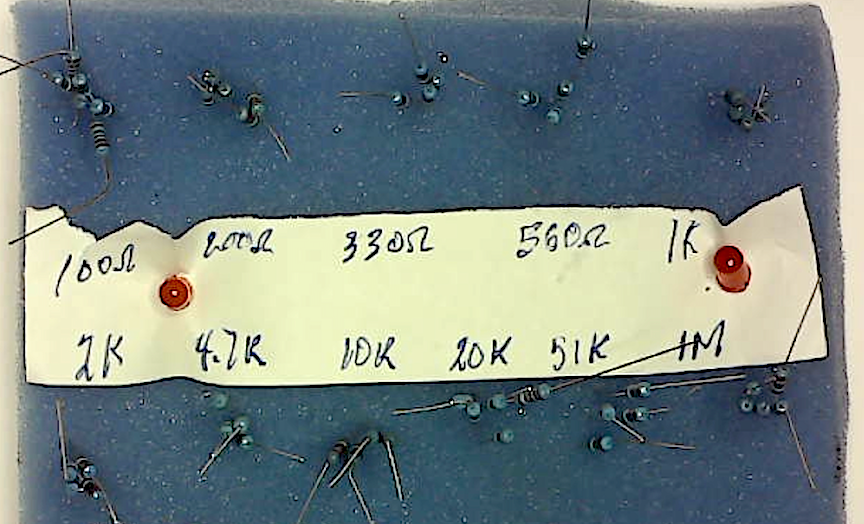 

        Fig. 1. Resistor collection stuck in foam, won't get scrambled when it falls off your desk. Paper label is affixed to foam with 2 LEDs. The values in your kit maybe different than shown above.

**Assessment: **Submit a photo of your resistor collection. You maybe inclined to blow this off, but this is a key piece of your electronics "apparatus" that you'll be using over and over. It's hard to make circuits that work, so don't make it harder by struggling to find the right resistor values. 

### 1. Characterize the wall wart 

**Preparing the wall wart**. 

- Cut the connector off the cord (you'll later need the connector with 8" of wire from your 12V dc adapter, so save it in your toolbox). 

- Cut one of the two wires ~1/2" shorter than the other (to reduce the chance of them touching and forming a short circuit). 

- Strip 1/8" of insulation off each end. 

- IF this is the first time using your soldering iron, BEFORE turning it on, familiarize yourself with it and how to solder (there are lots of youtube videos). Don't overheat the tip, make it just hot enough to quickly melt solder, ...

- Solder ~1/4-1/2" of a 10MOhm (sacrificial) resistor lead perpendicular to each wire to facilitate connecting the cord to the solderless breadboard. 

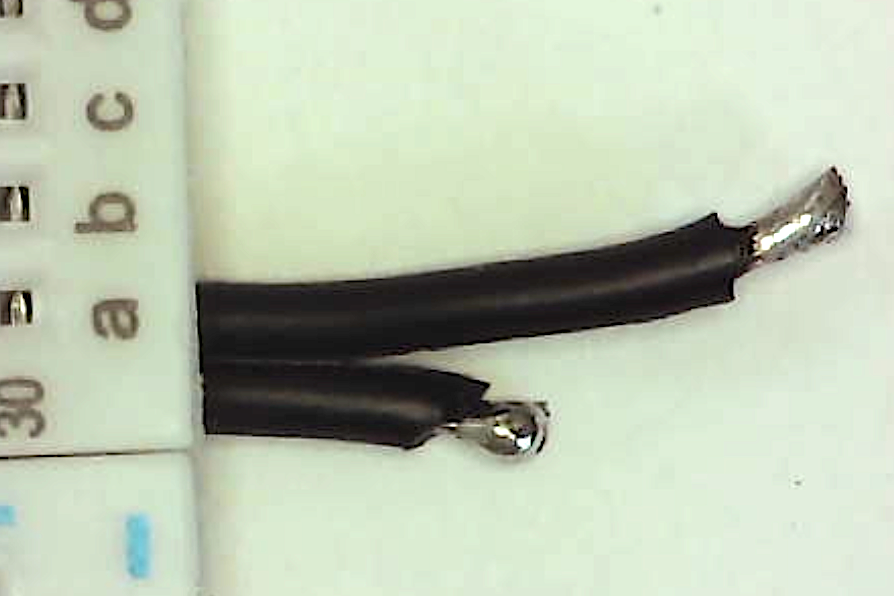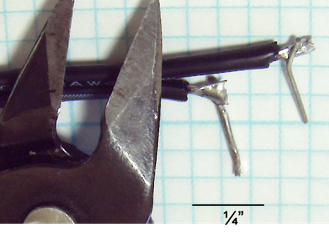

        Fig. 2. Sacrificial resistor leads soldered onto stranded wall wart wires facilitate insertion into breadboard. Offset reduces chance of shorting. First melt solder into the wire strands (left) before melting resistor leads.

**Measuring Vthevenin**. The simplest "model" of the wall wart is that of an ideal DC power supply. There is one parameter, the "open circuit" voltage, also known as the Thevenin voltage. Use alligator clips to connect your DVM to the power supply leads, set the DVM on VDC, and plug in the wall wart. Troubleshoot if your answer is unexpected. 

**Measuring Rthevenin**. A more accurate model of a voltage supply adds a series resistance, called Rthevenin after [https://en.wikipedia.org/wiki/Léon_Charles_Thévenin.](https://en.wikipedia.org/wiki/L%C3%A9on_Charles_Th%C3%A9venin.) This generally isn't a physical resistor, but an equivalent parameter with units of resistance, and we'll have to measure it indirectly. (BTW, setting your voltmeter to Resistance and connecting it to the plugged-in wall wart will likely DESTROY your voltmeter -- DON'T TRY IT!). With the DVM connected to the power supply as above, add a 1k or 100ohm resistor in parallel, and (quickly) record the voltage and (carefully) remove the resistor. A 100 ohm resistor will get dangerously hot (power ~ V^2/R ~ 144/100 ~1.4 Watts, and these resistors are rated to dissapate 1/4W at ~100°C). 

Compute Rthevenin using the voltage divider equation. You measured Vthevenin and V1. You know R1, so there is just one unknown (and algebra) left in the voltage divider equation.

### 2. Characterizing the LED

Voltage and current are not independent variables in 2 terminal electronic devices. Our goal now is to measure the relation between voltage and current for an LED. First a tip: LEDs are *easily* destroyed when their current limits are exceeded, so when connecting a LED to a voltage source, *ALWAYS ENSURE THERE IS A CURRENT LIMITER*. Said another way, always have a resistor (or equivalent) in series with an LED and a voltage source. The schematic below will let us safely measure the I-V characteristics of an LED. R1 = 1-2Kohm resistor will set the maximum current and also provide a convenient means to measure the LED's current. The 10k pot is effectively a voltage divider with R1, and will let us vary the LED's voltage (and current). 

Use an alligator clip to connect the black lead of the DVM to the node between R1 and the LED. For each position of the pot, move the red DVM lead (Fig. 3A, label A) alternately to the other side of R1 (Fig. 3A, label B) and the LED anode (positive side, Fig. 3A, label C) and record (minus) VR1 and VLED in a table.  

        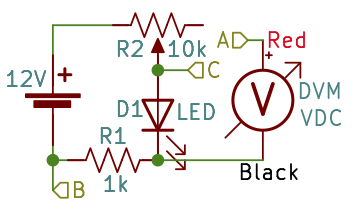 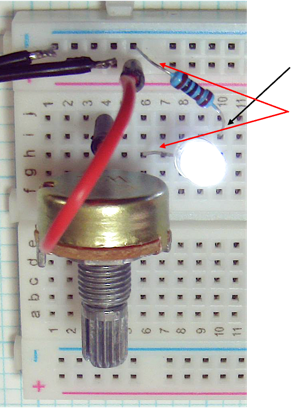

        Fig. 3. Schematic of circuit to measure LED I-V characteristic curve and implementation on a solderless breadboard. Alternate the voltmeter's red lead (labeled A) between the other sides of R1 (labeled B) and the LED (labeled C) to measure (minus) VR1  and VLED respectively, for various positions of potentiometer R2. 

Because it's a series circuit, the current through each component is the same. Ohm's Law tells us what that current is: I = VR1/R1 = ILED. (Why not measure I = VR2 / R2? ... Because you'd also have to measure R2 each time it changes when you rotate the knob.)

Don't forget to add (VLED, ILED) = (0,0) to the data. Also be aware of what your units are and that they are consistent. E.g., mA = A/1000 is a more natural unit of current in this circuit. 

### 3. Choosing a brightness

The LED's brightness varies along its characteristic curve. LED efficiency at converting power to light is relatively constant (if it's temperature doesn't change), so brightness is approximately proportional to P = VLED * ILED. Choose a desired brightness, and measure the corresponding VLED and ILED. 

### 4. Designing the night light

Our design goal is a series circuit with one resistance in series with the LED that replaces the pot R2 and R1 while keeping the LED at its desired brightness (i.e., current). Solve for that resistance using KVL in Fig. 4. Compromises will probably be necessary given our limited choices of resistor values. 

Explore how to acheive the desired resistance using series and/or parallel combinations of the resistor values that you have. 

**Assessments: **Assume you have resistor values of 100, 330, 1k, 2k, 5.1k, and 10k ohms. 1) How would you make ~900$\Omega$ with 2 resistors? 2) How would you make 1200$\Omega$ with 2 resistors? 3) How would you make 1.44k with 2 resistors? 4) How would you make 1.33k with 2 resistors?

### 5. Prototyping and validating the design

Construct the circuit above on the solderless breadboard and measure all voltages. Troubleshoot if any surprises. 

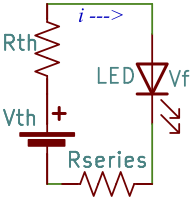

        Fig. 4. Replacing R1 and R2 with an equivalent resistor (or resistors in series or parallel), Rseries, to achieve the desired brightness on the I-V curve without the pot. 

### 6. Construction (soldering and heat shrink)

The final step is to solder a clean and safe nightlight. Practice soldering techniques, heat shrink, and take a photo of your final light (turned on).  

## Results

### 1. Wall wart Thevenin equivalent

Vthevenin = 12.17; % volts, measured open circuit
Rload = 101.0-1.3; % ohms -- measured with ohmmeter
Vload = 12.10; % measured across Rload
Rthevenin = rthevenin(Vthevenin,Vload,Rload) % homework -- figure it out. 

Rthevenin = 0.5768

Troubleshoot if Rthevenin > ~ 10 Ohms. An ideal voltage source has Rthevenin = 0 Ohms.

### 2. LED I-V curve

Upon seeing missing data at the bottom, a 100k and then 1M resistor were added in series to the circuit providing the two lowest data points:

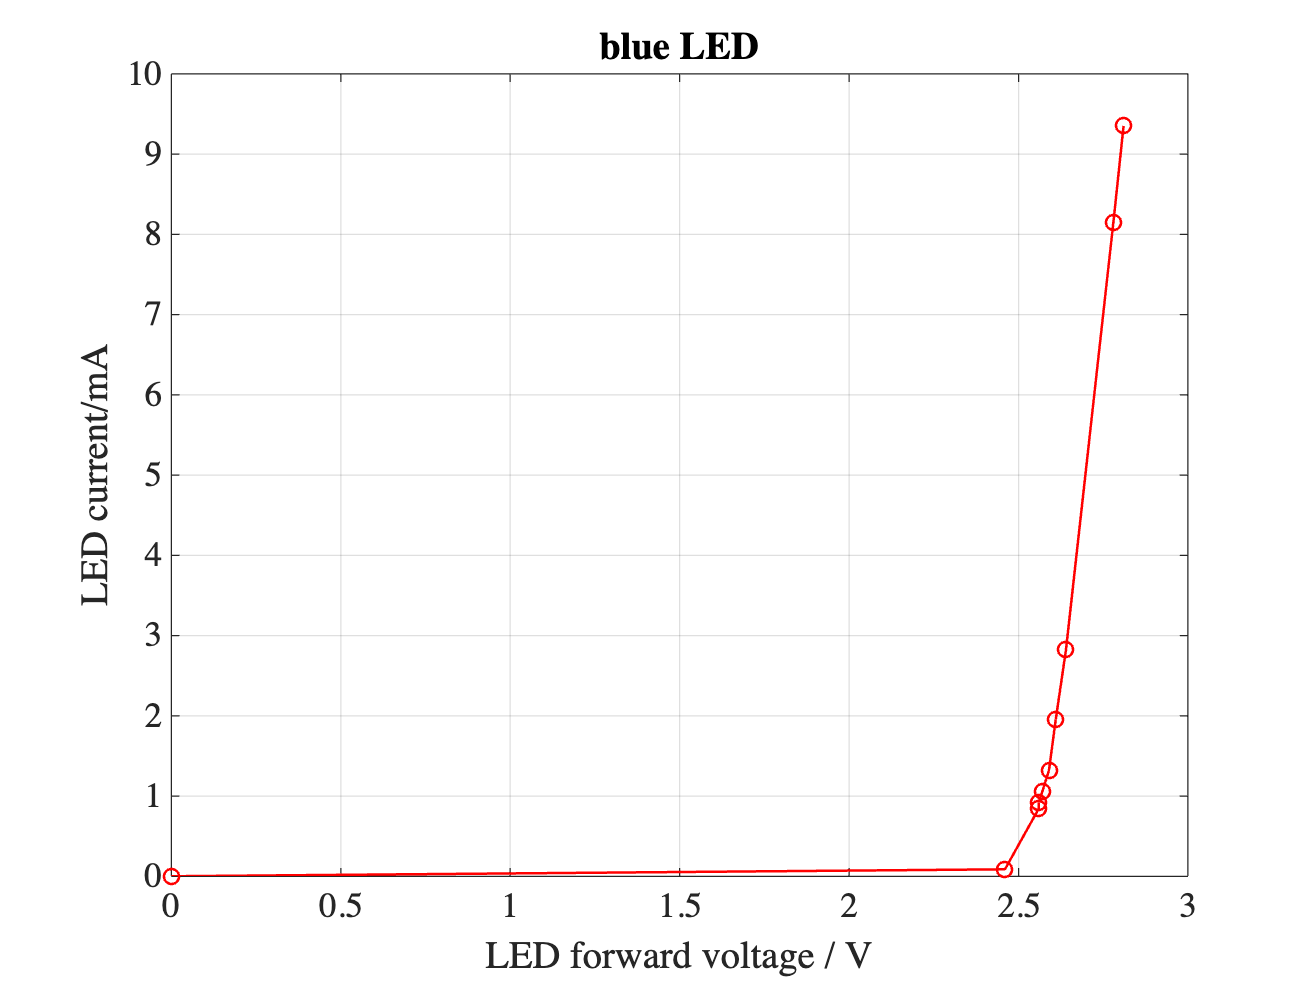

Vd = [0  2.46 2.56 2.56 2.57 2.59 2.61 2.64 2.78 2.81]; % volts across led
Vr = [0 .0865 .845 .917 1.052 1.322 1.957 2.82 8.15 9.35 ];% volts across both R and led
R1 = 1000.0; % ohms
id = Vr / R1 * 1000; % mA
plot(Vd,id, 'o-')
xlabel('LED forward voltage / V');
ylabel('LED current/mA');
grid
title('blue LED')

        Fig. 5. Measured LED I-V curve. 

Does your i-v curve have the expected characteristics (shape) for a diode, i.e., a "hockystick", flat below the "knee" voltage, $V_f$, and ~exponential or nearly vertical to the right? If not, then troubleshoot what you did wrong. 

Is your i-v curve a mess because the data you collected aren't monotonic? Matlab can `sort` the data, but you have to reorder both Vd and Vr the same way, e.g., to force Vr to be monotonically increasing:

[Vr, indx] = sort(Vr); 
Vd = Vd(indx); % reorder Vd the same way
% now redo the plot

The next step is choosing a point on the characteristic curve that you wish to operate the night light at -- what forward voltage and current result in your desired brightness?

i = 5e-3; % amps
Vf = 2.7; % volts LED forward voltage
Rseries = (Vthevenin - Vf)/i; % ohms
fprintf('Rseries = %.0f ohms\n', Rseries);

Rseries = 8606 ohms


As is typically the case, I don't have a resistor of precisely that value so I pick a nearby value and expect the LED's operating point to shift up or down accordingly along the characteristic curve. Keep in mind that our perception of brightness is roughly logarithmic, so 10% differences in brightness are hardly perceivable. 

### 3. Design and Prototype

Validating the design

Rseries = 9.97e3; % 
Vrseries = 9.601; % volts measured
Vled = 2.608; % volts measured
i = Vrseries / Rseries * 1000 % mA

i = 0.9630

% power calculations
Presistors = Vrseries^2 / Rseries * 1e3 % mW

Presistors = 9.2457

Pled = Vled * i % mW

Pled = 2.5115

These are well below dangerous limits for these components (the resistors are rated for 250mW -- note they will likely be ~ 100°C at that power level, so although the component will survive, it doesn't mean it is safe for you to have in a night light circuit. I'm guessing the LED can safely dissapate up to 25-50mW, so everything in this circuit should run cool and last practically forever.

### 4. Construction

Insulation between the leads of the LED would prevent them from shorting, but so would cutting them short. LEDs are susceptable to thermal damage, so short leads should be soldered quickly. First melt solder on each of the resistor leads, LED leads, and wire ends, before attempting any connections. With solder on each terminal, you no longer need to hold the solder to make the connections. One hand holds the iron, the other aligns two leads, and a quick touch to a dab of melted solder on the iron joins the leads. 

The power supply connections are physically offset, so a short of the LED leads would still leave the Rseries resistor in the circuit. Such a short would make the LED's voltage zero, so no light, and since no Vf = 2V in the circuit, Rseries would experience the full voltage, and dissapate: 

PshortedLED = Vthevenin^2 / Rseries * 1000 % mW

PshortedLED = 14.8555

Well within safey limits. The light will stop working if the LED pins shorted, but there's no risk of fire or damage. It's always good to anticipate and plan for the most probable failure case.

### 5. Final photos

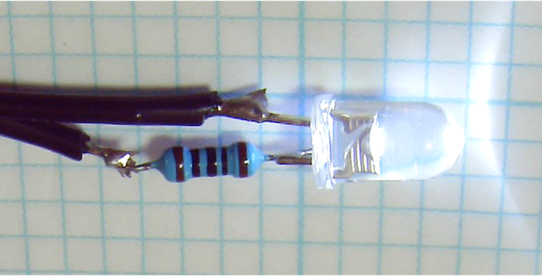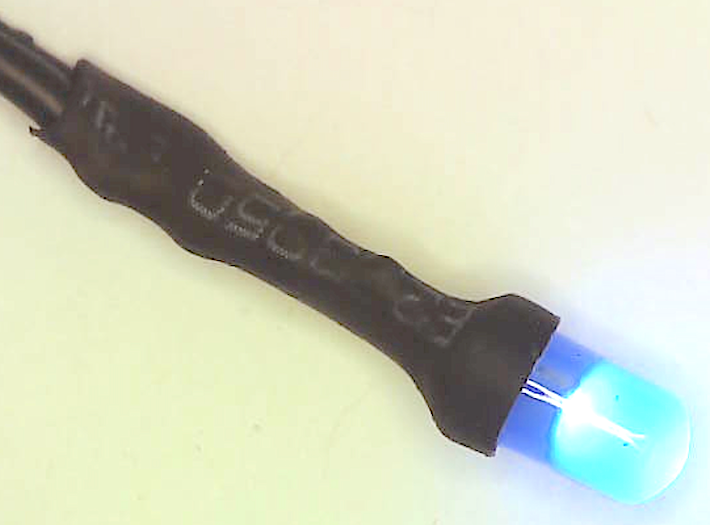

        Fig. 6. Soldered LED night light, without insulation on the (low-voltage) wires. Note the offsets and short leads reduce the risk of the wires shorting. Picture of a finished nightlight after heating heat shrink (with the hot stem, NOT the tip, of the soldering iron). 

### 6. Simulation and modeling

        Fig. 3. Circuit used to measure LED's I-V curve.

The 10k pot (more precisely, the center and end terminal of it that was in the circuit) varied the total resistance in the circuit. The voltage drop across it, Vpot =  i*Rpot, reduced the voltage across the rest of the circuit. Kirchoff's Voltage Law states the sum of the voltages around the circuit are zero, so more `Vpot` means less `iR1` and since `R1` is fixed, less current $i$ through the LED (current is the same for every device, by Kirchhoff's Current Law). Assuming you phrased it differently, is your explanation correct or does it contain misconceptions or misstatements? [PAUSE]. Another way to describe this circuit is to realize that it doesn't matter that the LED is between R2 and R1, those two resistors are still in series, and thus *are* voltage dividers. 

We can make a simplfied model of Fig. 3 by first assuming the LED's voltage above it's knee is constant, e.g., 2V. That allows us to replace the LED symbol in Fig. 1 by a 2V battery. What polarity does it have? Is the top of the LED in Fig. 1 positive or negative [PAUSE]. Current enters the top making it positive relative to bottom, So the LED's "battery" opposes or cancels 2V of the 12.2V supply letting us simplify to an equivalent circuit with a single 12.2-VLED volt source, that's in series with voltage dividers R2 and R1. We can model the current in this circuit just as we did in Chapter 1, expressed below in Matlab code. What value should we model for the pot R2? [PAUSE]. Why not *all values*, or 100 equally spaced ones between 0-10k: 

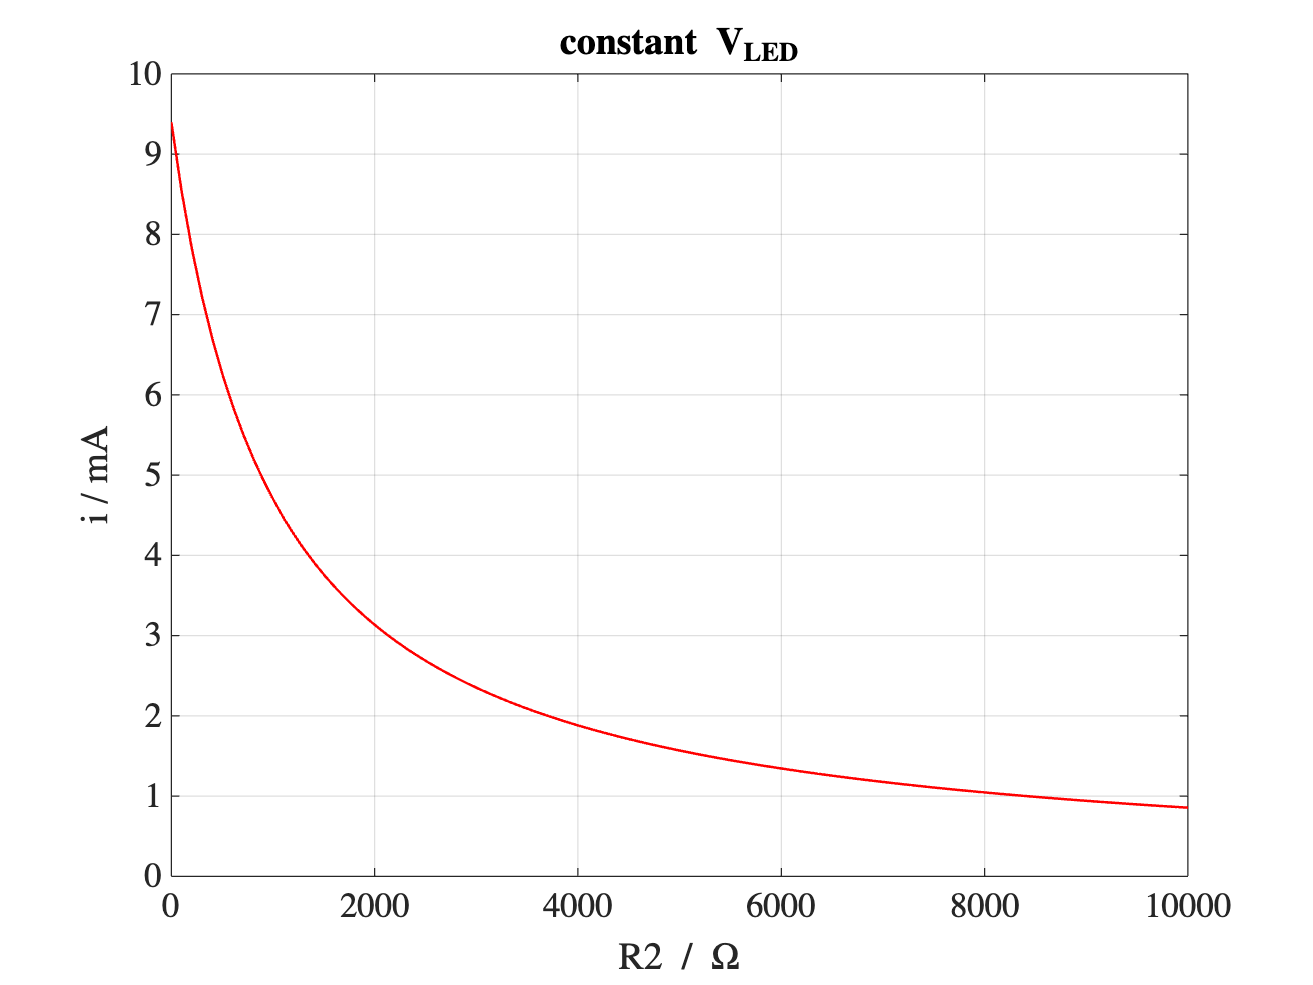

% model of Fig. 1 with constant VLED
R2 = linspace(0,10e3)'; % a column array of values in ohms
R1 = 1e3; % ohms
Vin = 12; % volts
VLED = 2.6; % volts assumed constant
VR1 = (Vin - VLED) * R1 ./ (R1+R2); % ./ "pointwise division" since R2 is an array
isim = VR1 / R1 * 1e3; % mA
plot(R2, isim);
xlabel('R2 / \Omega'); ylabel('i / mA')
title('constant V_{LED}')
grid;

        Fig. 7. Simple model of Fig. 3, showing how/why it worked to measure a LED's I-V curve. 

This curve doesn't look like anything we measured before ... because we didn't measure these parameters, current vs. R2 position. To test if this model describes our circuit, first figure out which position of R2's knob corresponds to the left and right sides of Fig. 7. Fig. 7 predicts that small changes in R2 near its minimum values result in large changes in LED brightness, and conversely, the slope $di/dR2$ gets smaller for  R2 > R1, and turning R2's knob has decreasing effect on dimming the LED. Verify that this is qualitatively what you see.

If we think of Fig. 3 as a voltage divider, then Fig. 7 also represents the "output voltage" across R1, since VR1 = $i$ * R1, and R1 is a constant (in particular if $i$ is in mA and R1 = 1k$\Omega$, then the y-axis of Fig. 7 also has units of volts across R1. So Fig. 3 is functionally a variable DC power supply -- with both the current and voltage (across R1) controlled by R2, but in a very nonlinear manner. Our next lab will be to build a much more useful power supply who's output voltage is a linear function of R2. Later, we'll teach our computer how to control its output voltage, so we won't have to manually turn R2. Then we'll be able to measure I-V curves (and much more) by a single keystroke ... but that's a few weeks away ...

## Discussion

What does Fig. 5 *mean*? Let's approximate it and the LEDs behavior as follows: When Vled < $V_{forward} = V_f$ ~ 2V, its current ~ 0 and it produces no light -- it's "off". If Vled = $V_f$, which is approximately a constant for each LED, the LED glows and dissipates power $P = V_f* i$ proportional to the *current* (since $V_f$ is approximately constant; contrast to a resistor, where $P = i^2/R$ is proportional to current squared). If you *try* to apply more than $V_f$ of voltage across the LED, it's current will increase extremely rapidly, and without adequate series resistance or other current limiting, the device will rapidly burn up. We can summarize thise results into the following practical rules to light an LED:

- The LED's (forward -- it's polarized) voltage must be a threshold value, $V_f$, characteristic of the LED. 

- LED current must be controlled by an external current-limiting element -- e.g., a series resistor, because even a tiny increase in $V_f$ results in a huge increase in current.

- Brightness and power is approximately proportional to current.

How did the model and Fig. 7 change your understanding? We could improve the model's accuracy (and complexity) by not assuming $V_{LED}$ were constant, but that wouldn't change the main conclusion -- that voltage and current are fundamentally nonlinear functions of R2's position. 

## Further questions

- What worked, what didn’t, why? Any surprises?

- How did theory and measurements agree and/or disagree? 

- How much power will your night light use, and what is its monthly cost to use? How can you further reduce that cost and should you?

- How did you measure the LED's current, without switching your DMM to current?

- What 2 key roles did R1 play in this circuit? What would have happened if R1 = 0 or 100 ohms?

- Did we achieve our Objective? Do our stated Methods describe what we did? Are our Results the consequences of following our stated Methods? In other words, is your lab report accurate? 

- In retrospect, did we do any unnecessary steps? Any shortcuts you can recommend? 

- How many Matlab functions did we use in this activity? Make a list of them with a terse description. If you don't understand them, ask Matlab, i.e.,: `>> help <name>` or `>> doc <name>`.

- Challenge question: Any 2 terminal device has a characteristic I-V curve. Sketch the I-V curve for a 1.5V battery, ignoring and including an Rth > 0. 